format longEng
j = 23 ; %NO OF LOG CORRECTION COEFFICIENT
a=-pi;
b=pi;


w = 2^0.5;

syms v(x) f(x)
v(x) = exp(2*cos(8*x) + sin(9*x));
f(x) = v(x)*log(w*(1-cos(x)) )

$$f(x) = {\mathrm{e}}^{2\,\cos\left(8\,x\right)+\sin\left(9\,x\right)}\,\log\left(-\sqrt{2}\,\left(\cos\left(x\right)-1\right)\right)$$



cor_l = 0; %to store log correction
sum = zeros(5,1); %log corrected approximation
counter = 1;
 n = 250;
    h = 2*pi/n ;
    %---------------------------
    coff = pre_val(j);
    
    cor_l =( log(w*h*h) + coff(1) )*v(0)*h;
    for r = 2:j  %calculating log correction
        cor_l = cor_l + h*coff(r)*(  v(-(r-1)*h) + v((r-1)*h)  );
    end
    %---------------------------
    %---------------------------

    for r = 1:n-1
        sum(counter) = sum(counter) + v(a + r*h)*f2(a + r*h);
    end
    sum(counter) = sum(counter) + 0.5*( v(a)*f2(a) + v(b)*f2(b) );
    sum(counter) = h*sum(counter) + cor_l ;
    
    
    counter = counter+1;

 
sum_r = -9.020018845802836;  

X = linspace(-1.9*pi,2*pi,100);
Y = double(f(X))

Y =    -721.267290743969e-003   -151.442552988848e-003   -385.490017860273e-003   -4.10427229948407e+000   -13.6341072009360e+000   -2.81424332017335e+000   -98.0188965052674e-003   -7.05075712931095e-003    6.73834605601360e-003    587.302354989920e-003    6.33111108857571e+000    3.06054325365039e+000    207.711632900320e-003    35.5293570202793e-003    99.1849625413201e-003    1.77468172727904e+000    13.1550173604241e+000    6.60325719845849e+000    518.944809421029e-003    82.1376772151372e-003    147.165921961812e-003    1.49524358113334e+000    8.87811165510176e+000    6.32927928002005e+000    909.709291414643e-003    179.115872459693e-003    194.866321967220e-003    852.128905002490e-003    3.35845112480168e+000    3.69832618919436e+000    1.24914863841620e+000    357.990111428593e-003    216.498684442400e-003    316.089705699875e-003    659.254949593990e-003    1.00794905338459e+000    725.080913816582e-003    200.915140987906e-003   -5.48857481194605e-003   -59.4572615507587e

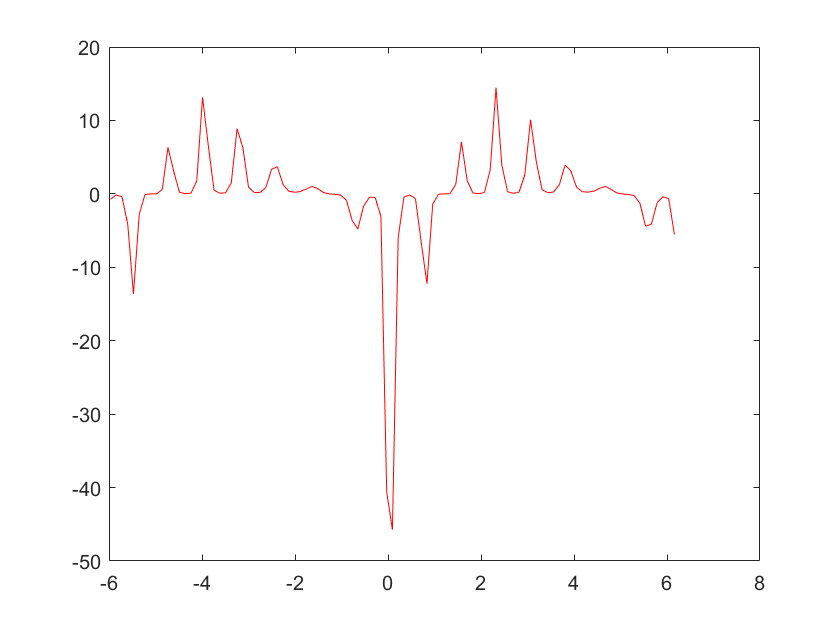

plot(X,Y,'color', 'r')


for i = 1:size(Y)
   if abs(X(i)) < 0
       disp("sds")
       Y(i) = 0.5*( v(a)*f2(a) + v(b)*f2(b) );
   end
end
plot(X,Y,'color', 'r')

function array =pre_val(n)
alp = 'D:\IISERB\thesis\Codes and other works\sem2\verification_Aguilar1\k' + string(n) + '.txt';
array =importdata(alp);
end

function ret=f2(x)
%to remove singularity
w = 2^(0.5);
    if (1 - cos(x)) == 0
        ret = 0;
    else
        ret = log(w*(1-cos(x)));
    end
end
